# **Proyecto de imagen**

Grupo 06

Componentes: Alexis Hermida, Noa Cereixo, André Costas, José Luis Rodríguez

## 1. Introdución

Este proyecto tiene como objetivo el reconocimiento de los caracteres presentes en diferentes imagenes con formato PNG. Para la resolución del mismo, se han desarrollado las seis tareas propuestas por el profesorado de la asignatura en las especificaciones del proyecto (binarización, segmentación de filas, segmentación de caracteres, procesamiento de caracteres, creación del alfabeto y reconocimiento de caracteres), con exitosos resultados.

NOTA: El correcto funcionamiento del mismo puede verse alterado si los caracteres no se hayan en el alfabeto inglés.

## 2. Banco de datos con archivos de imagen

Para la evalución del correcto funcionamiento del proyecto, se ha generado un banco de datos, que incluye un total de cinco archivos de imagen. Estos archivo se corresponden con los especificados en el siguiente tabla:

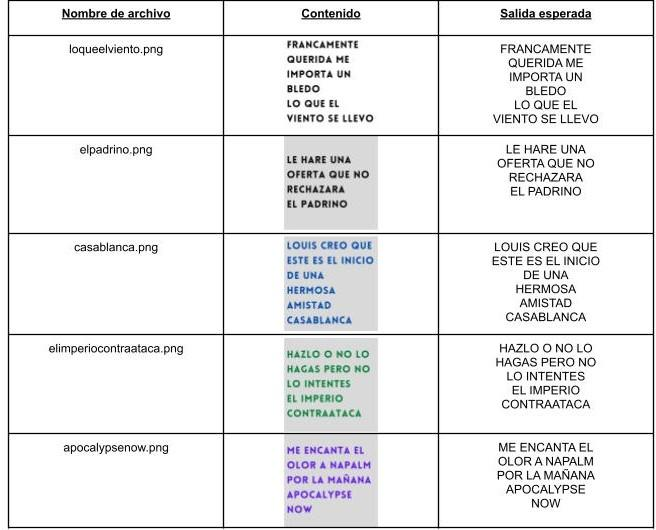

Además, dicho banco de datos también incluye el alfabeto con los distintos caracteres que se tomarán como referentes en la tarea final: *Recoocimiento de caracteres*.

: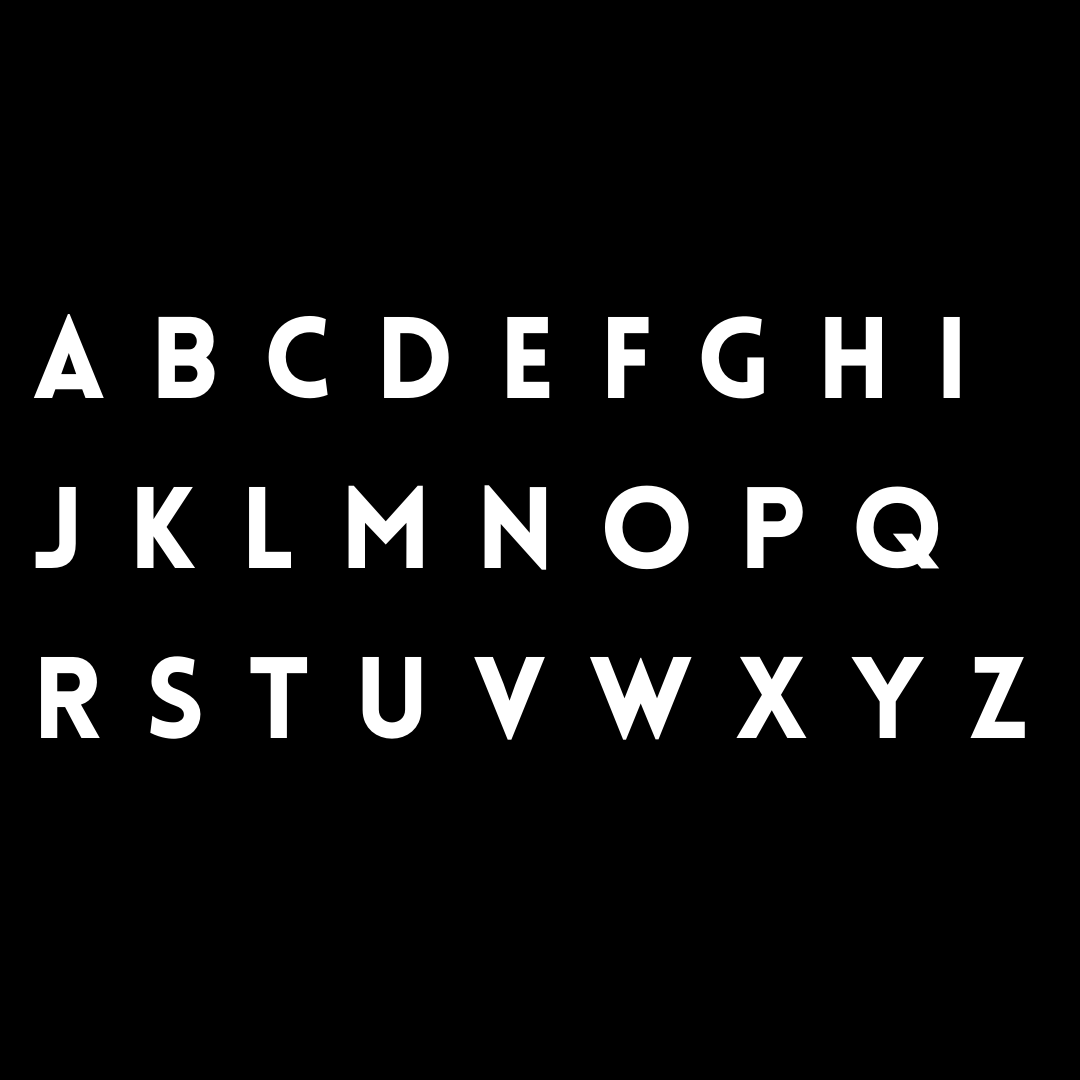

## 3. Reconocimiento de caracteres

En este apartado se desarrolla el código necesario para el reconocimiento de los caracteres presentes en las imágenes del banco de datos.

### Tarea 1: Binarizacion

En esta primera tarea, se procede a la lectura y binarización de las imágenes contenidas en los archivos del banco de datos. Al binzarizar la imagen, mediante la función *binarizar*, el fondo se visualizará en negro (valor 0 en la matriz) y los caracteres en blanco (valor 1 en la matriz). Además, se muestra por pantalla, tanto el contenido original de la imagen, como su resultado tras la binzarización.

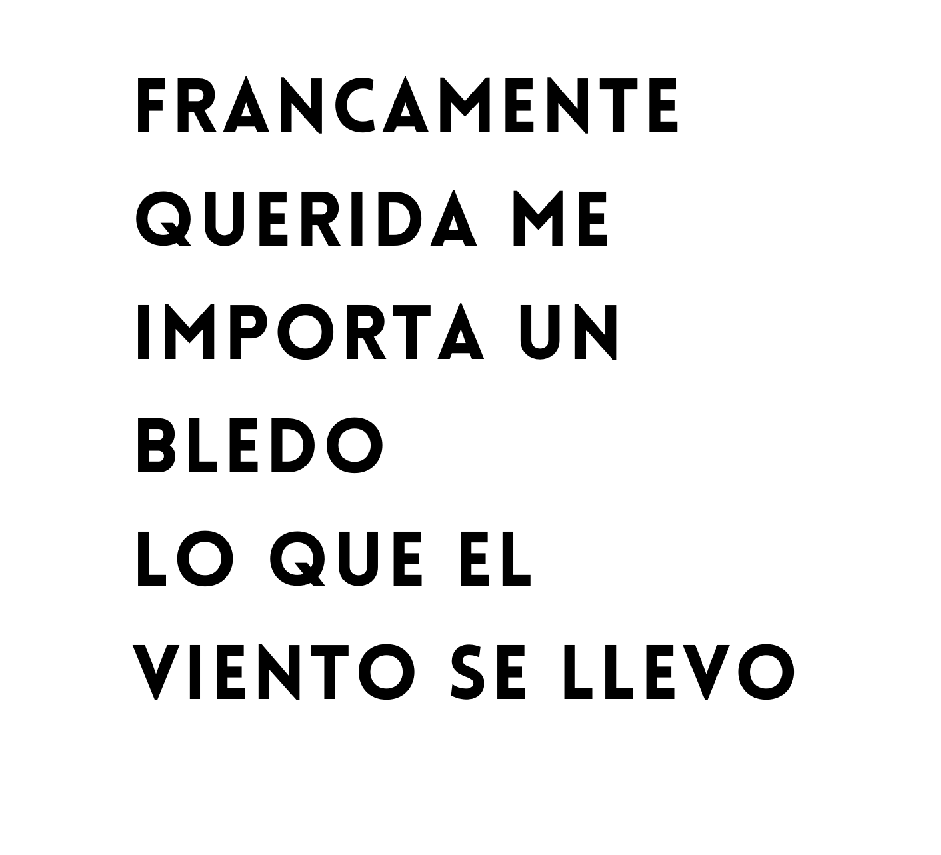

im1=imread("loqueelviento.png");
imshow(im1)

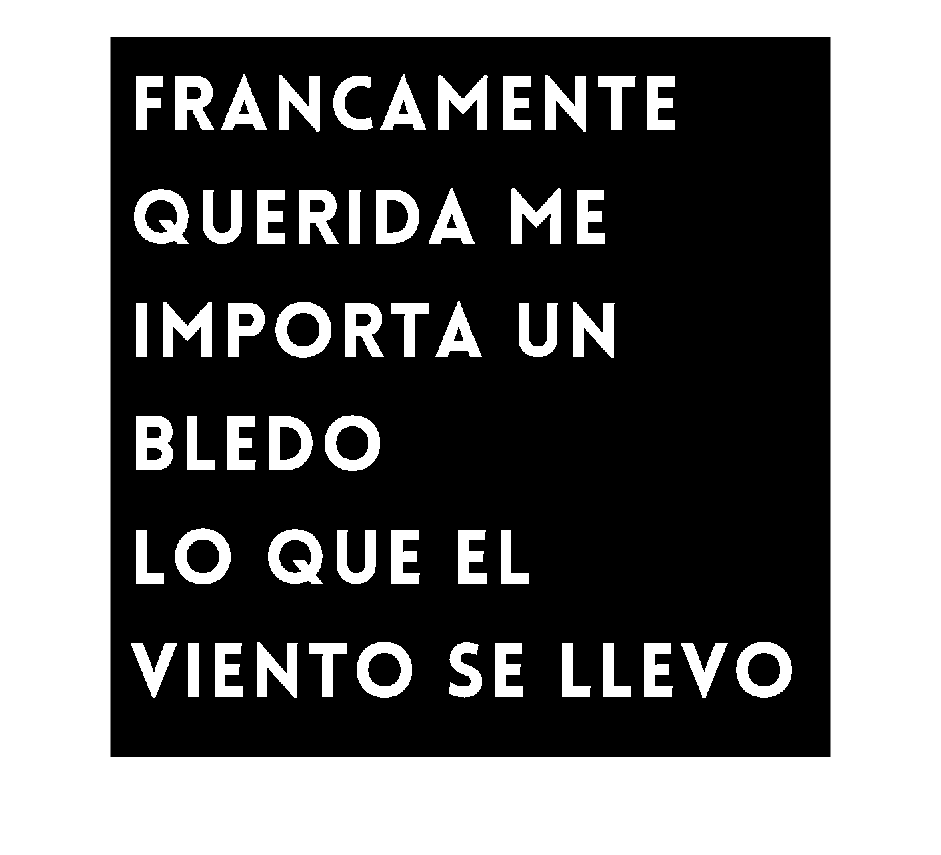

im1=binarizacion(im1);

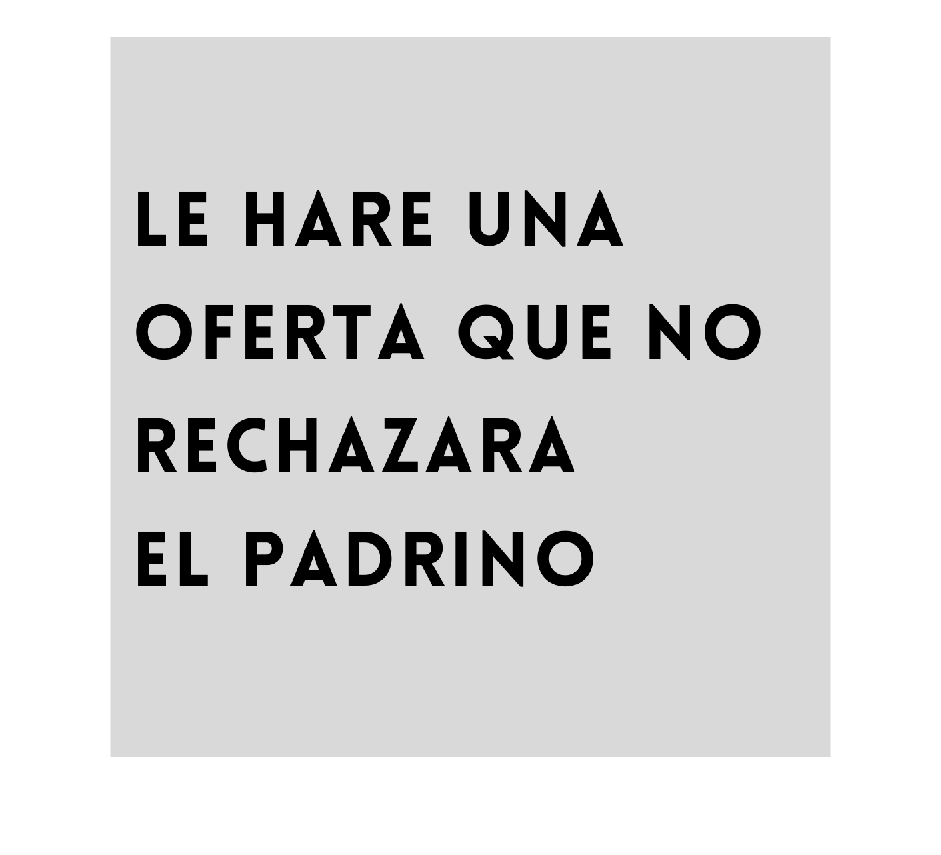


im2=imread("elpadrino.png");
imshow(im2)

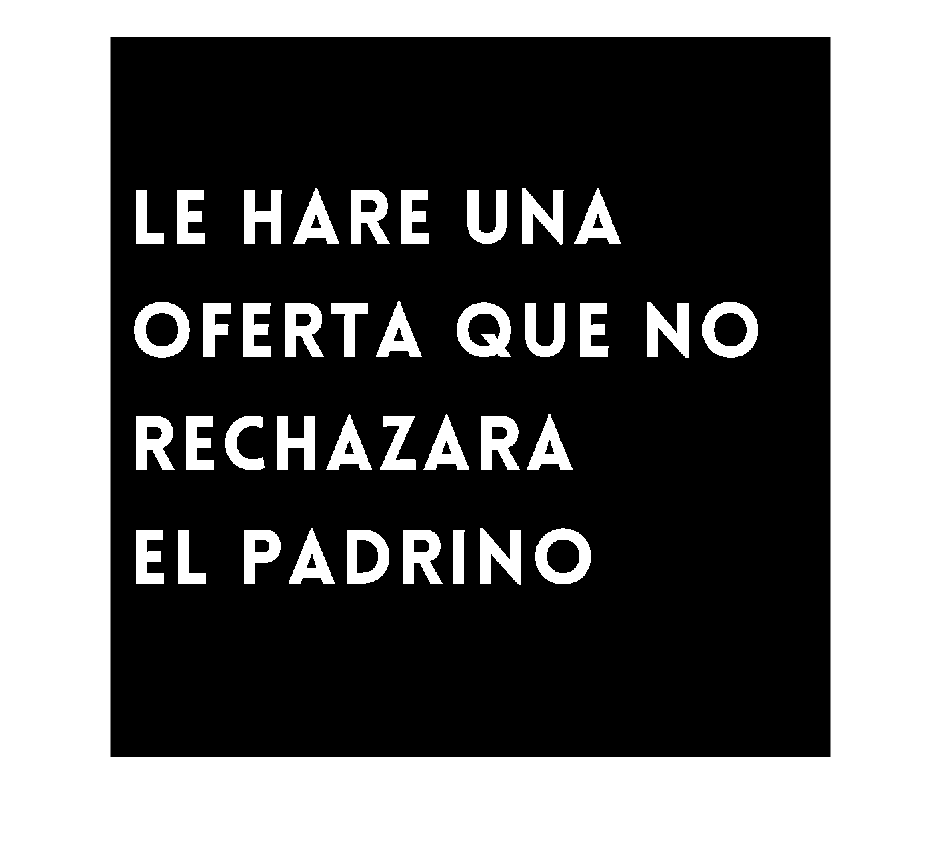

im2=binarizacion(im2);

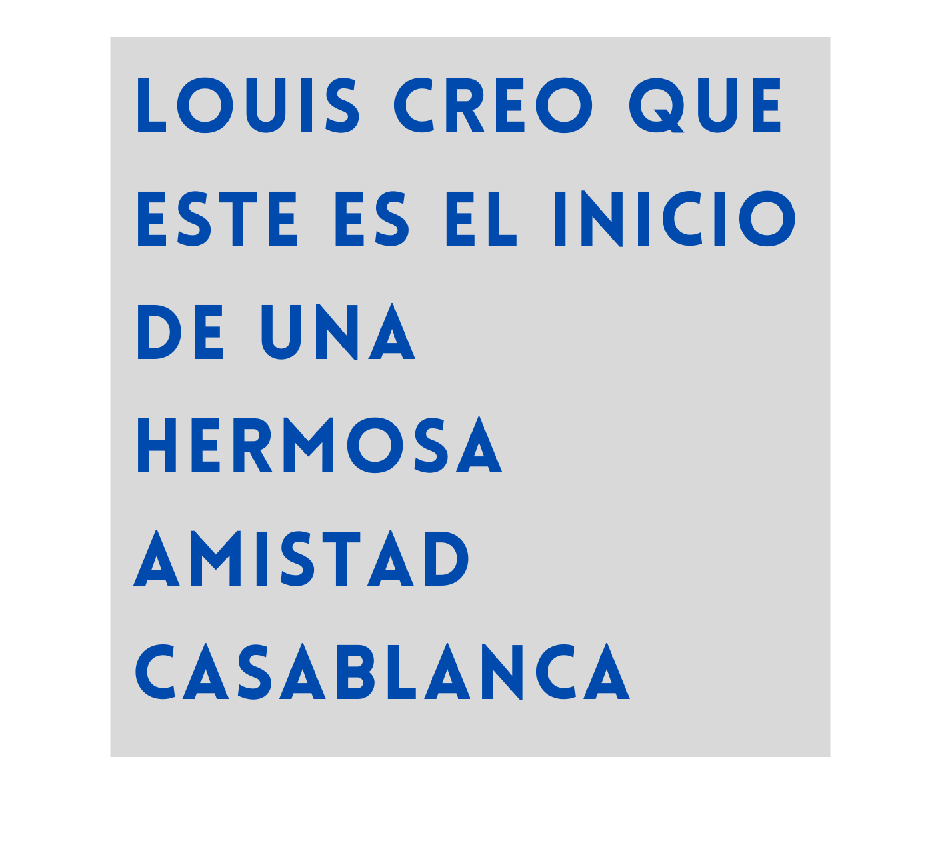


im3=imread("casablanca.png");
imshow(im3)

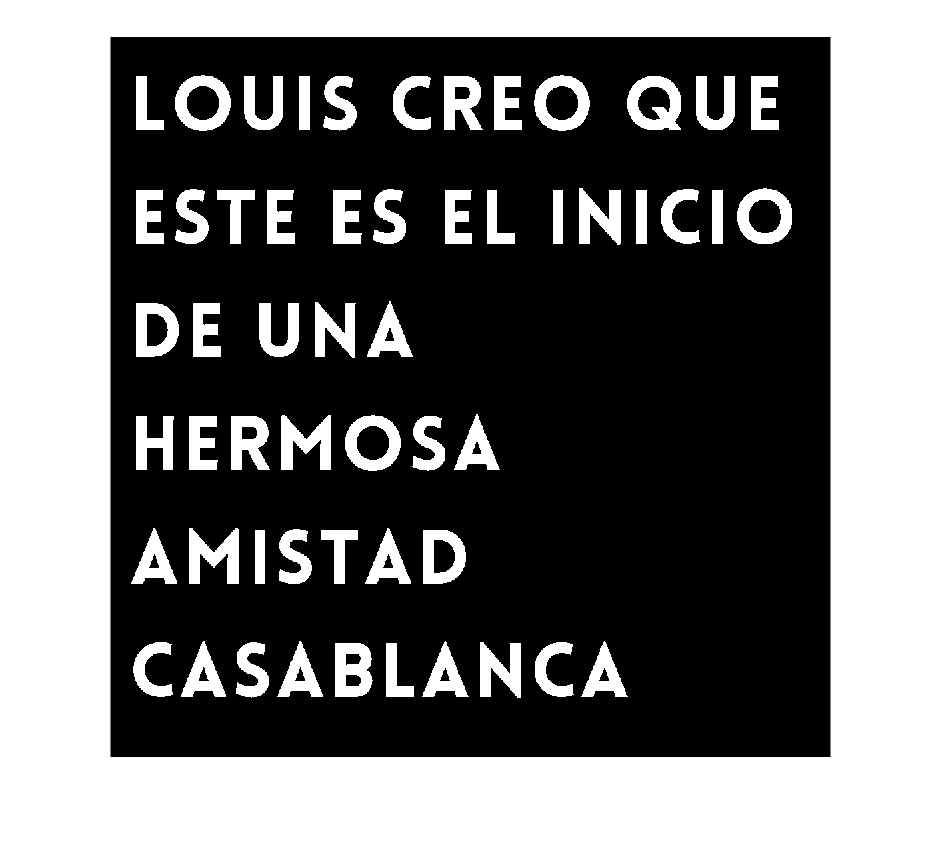

im3=binarizacion(im3);

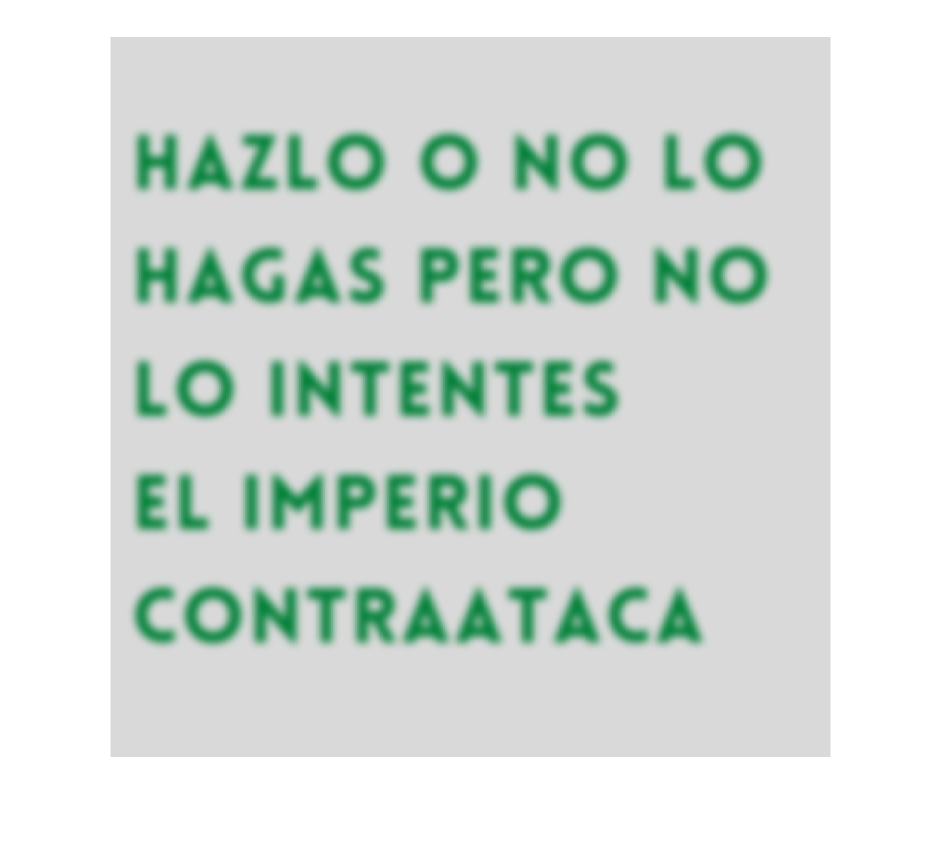


im4=imread("elimperiocontraataca.png");
imshow(im4)

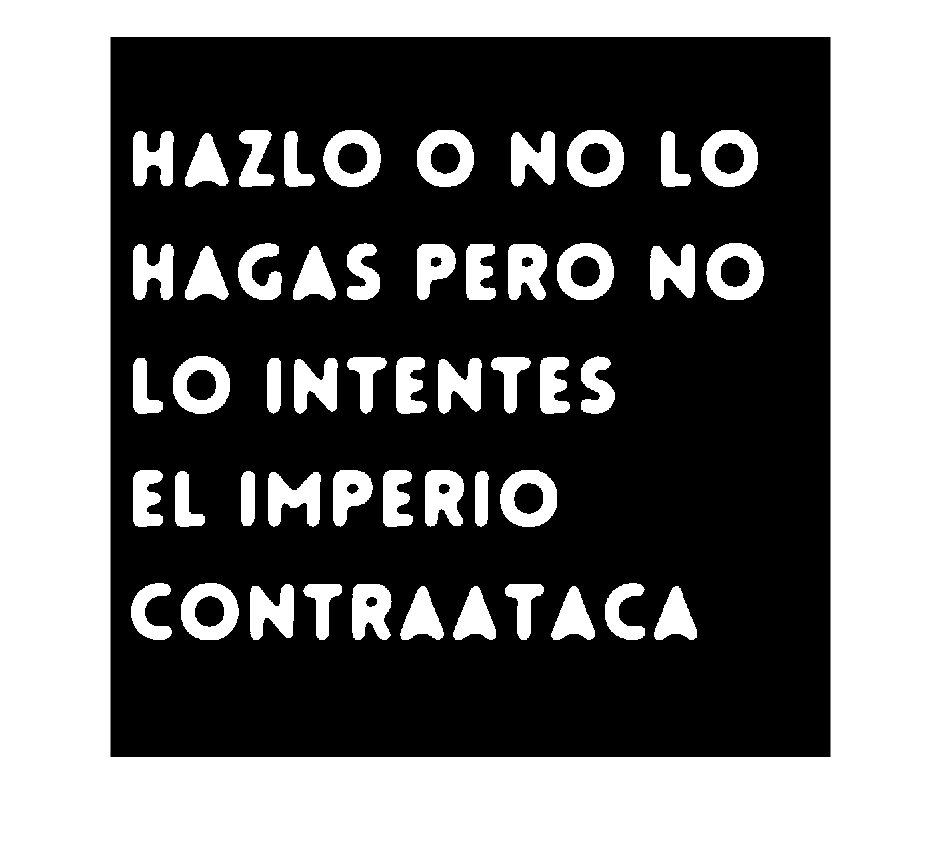

im4=binarizacion(im4);

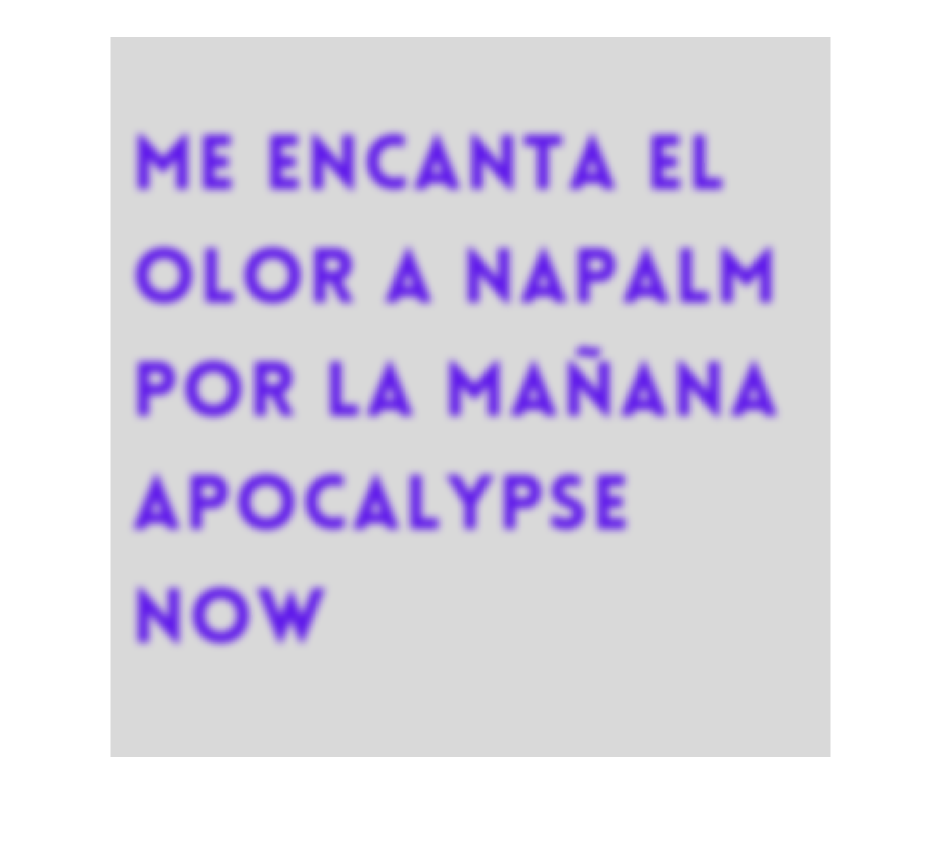


im5=imread("apocalypsenow.png");
imshow(im5)

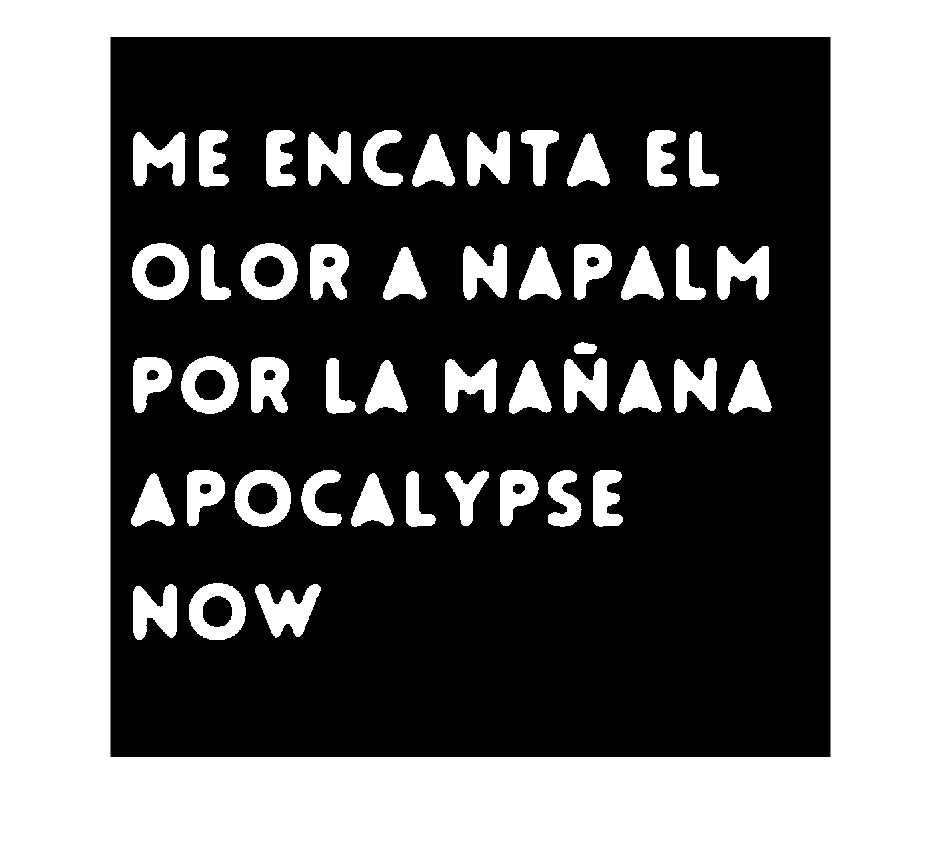

im5=binarizacion(im5);

### Tarea 2: Segmenación de filas

Con la invocación de la función *numFilas*, hayamos el número de filas de la imagen, así como los índices de la matriz donde comienza y finaliza cada una de ellas. Esta función muestra por pantalla la gráfica del vector surgido de la suma de las filas de la matriz de la imagen, así como la gráfica de un vector que toma valor 1 si el índice de la matriz forma parte de de una fila y 0 en caso contrario.

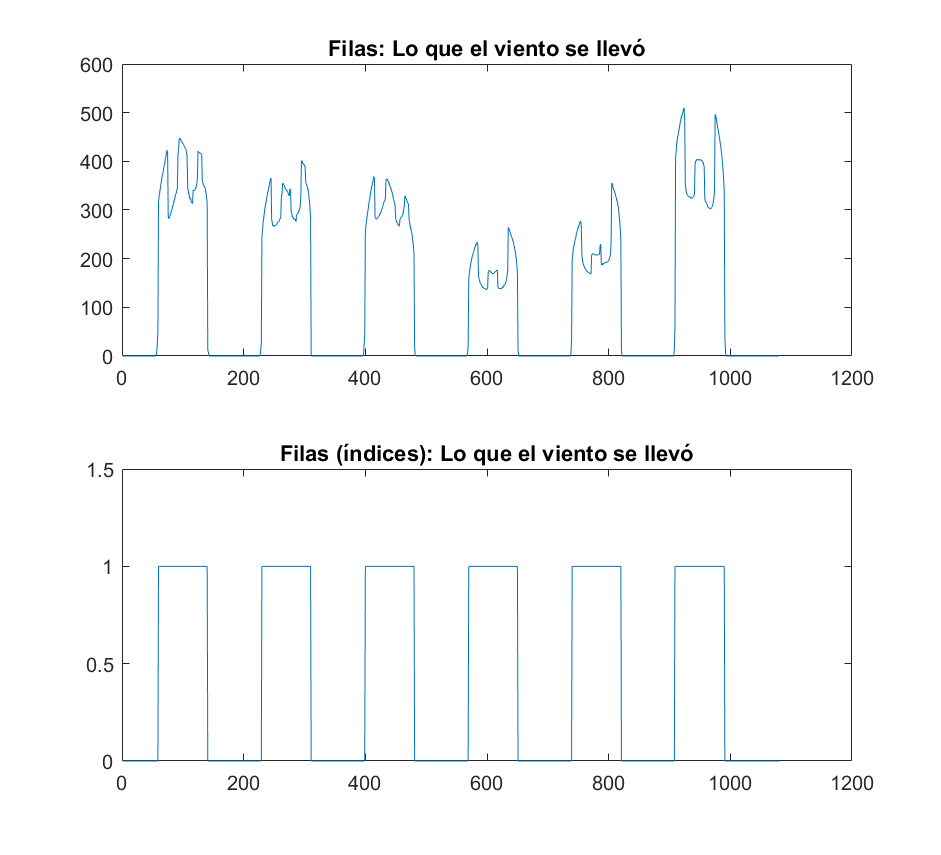

[filas1,indices1]=numFilas(im1,'Lo que el viento se llevó');

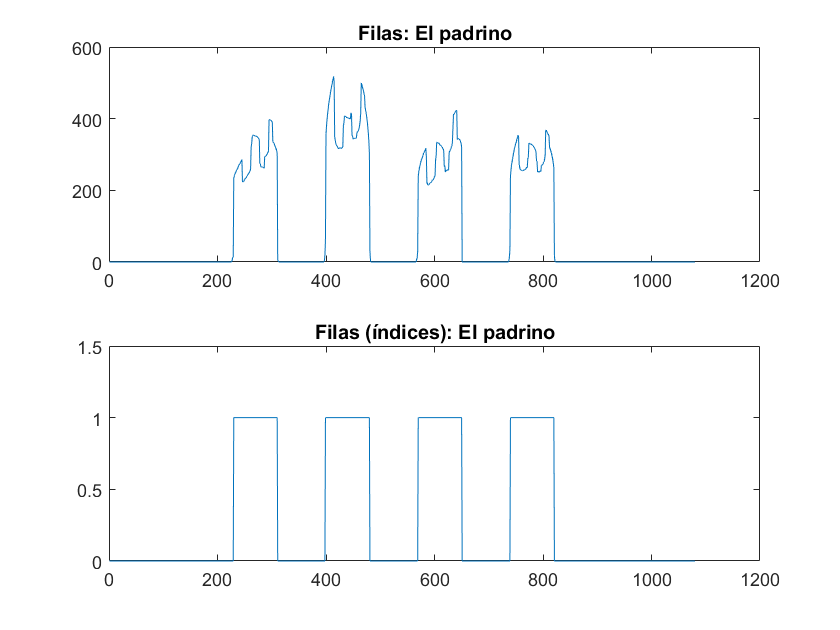


[filas2,indices2]=numFilas(im2,'El padrino');

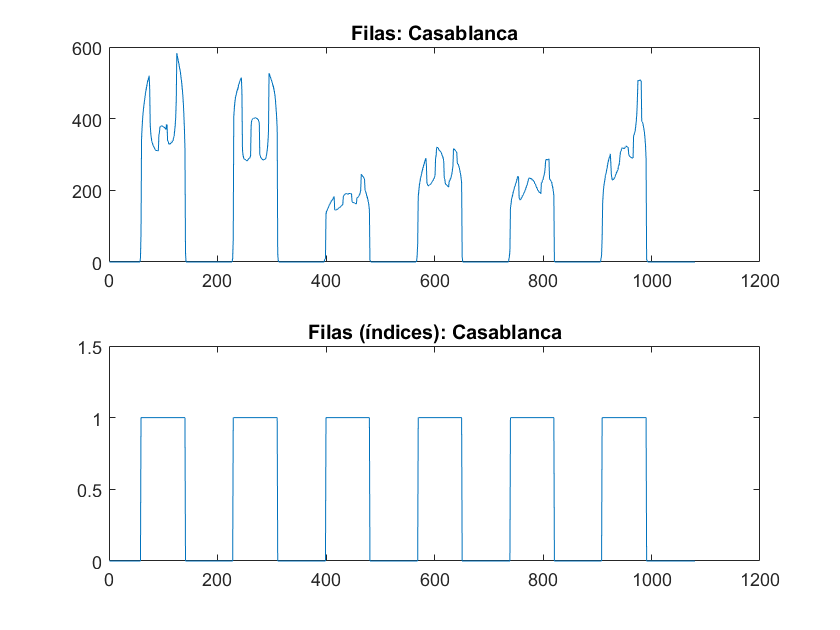


[filas3,indices3]=numFilas(im3,'Casablanca');

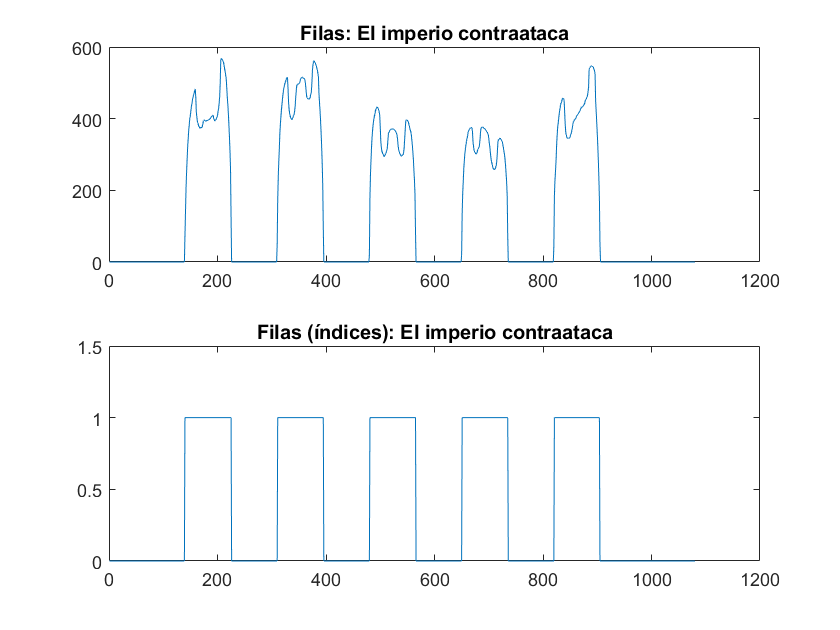


[filas4,indices4]=numFilas(im4,'El imperio contraataca');

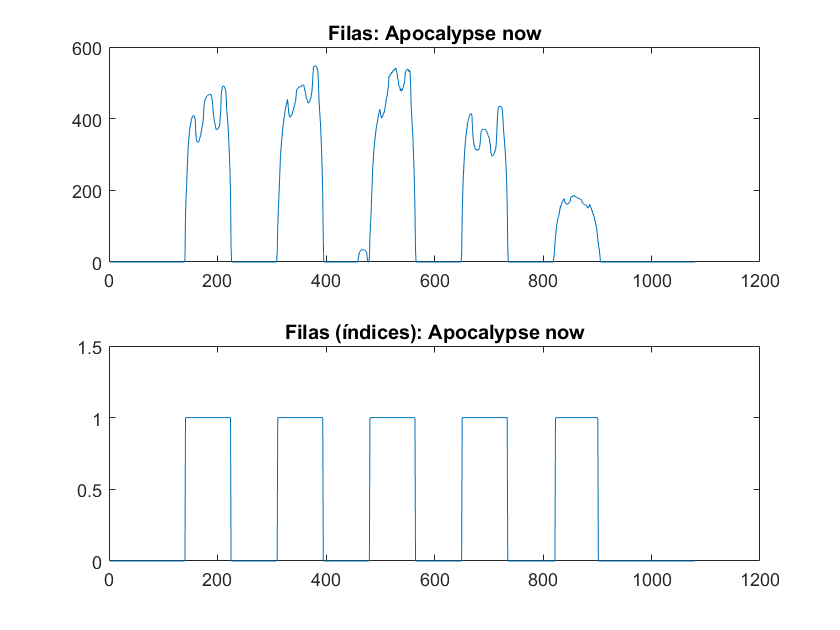


[filas5,indices5]=numFilas(im5,'Apocalypse now');

### Tarea 3: Segmentación de caracteres

La segmentación de caracteres se desarrolla de forma análoga a la segmentación de filas. En este caso, la función *numCaracteres*, muestra por pantalla tantas gráficas como filas presente la imagen. Cada una de ellas, contiene la representación del vector calculado a partir de la suma de las columnas de la matriz de una fila determinada.

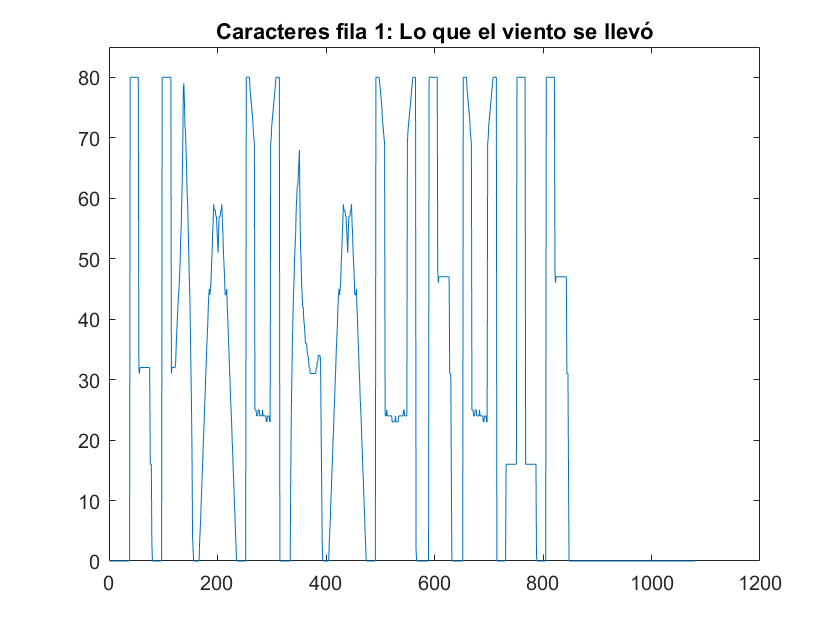

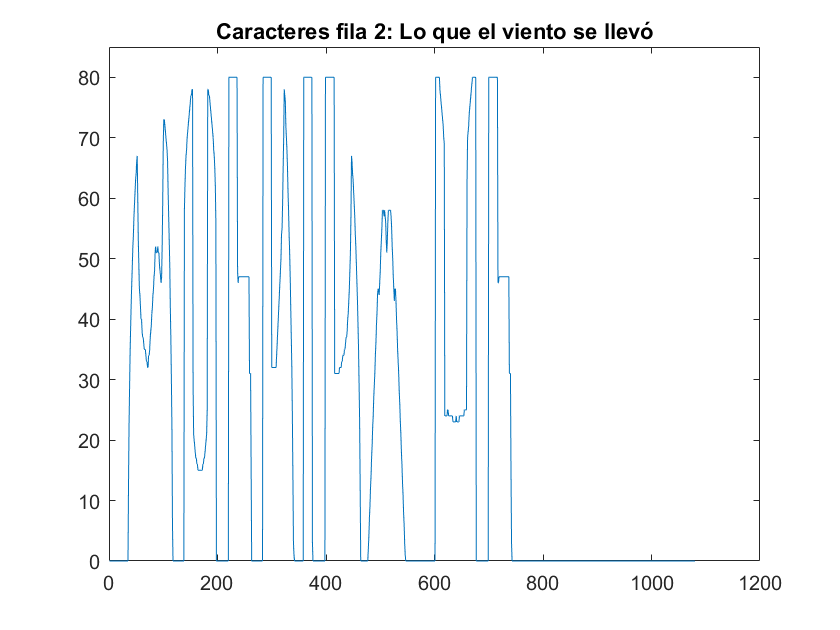

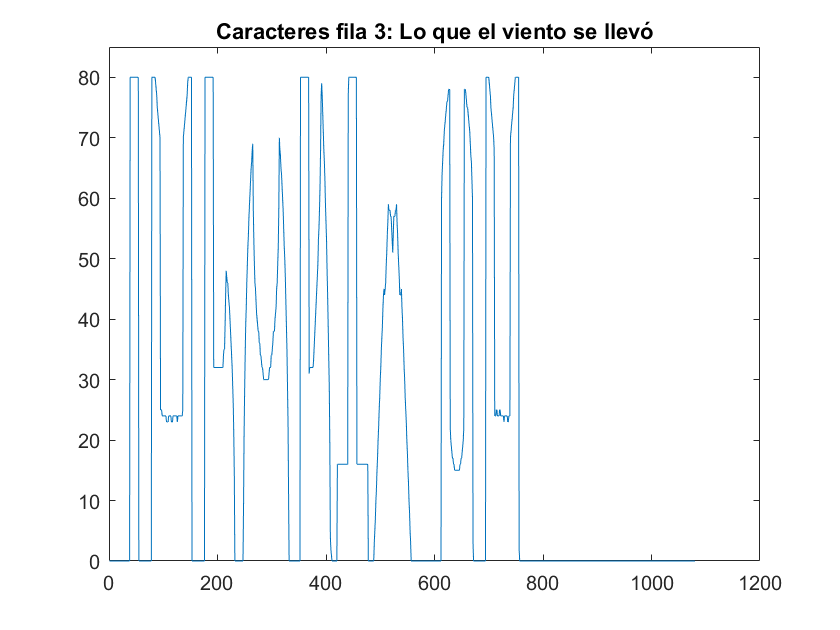

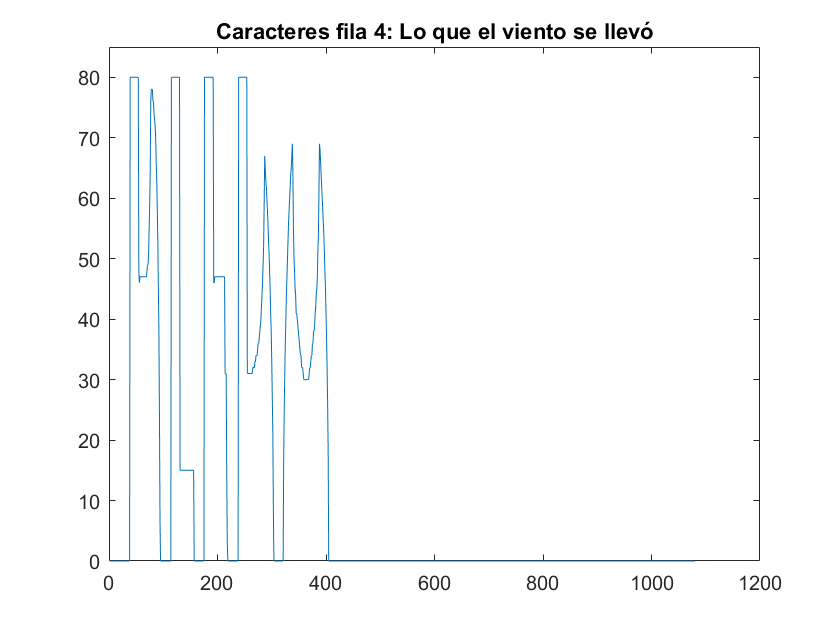

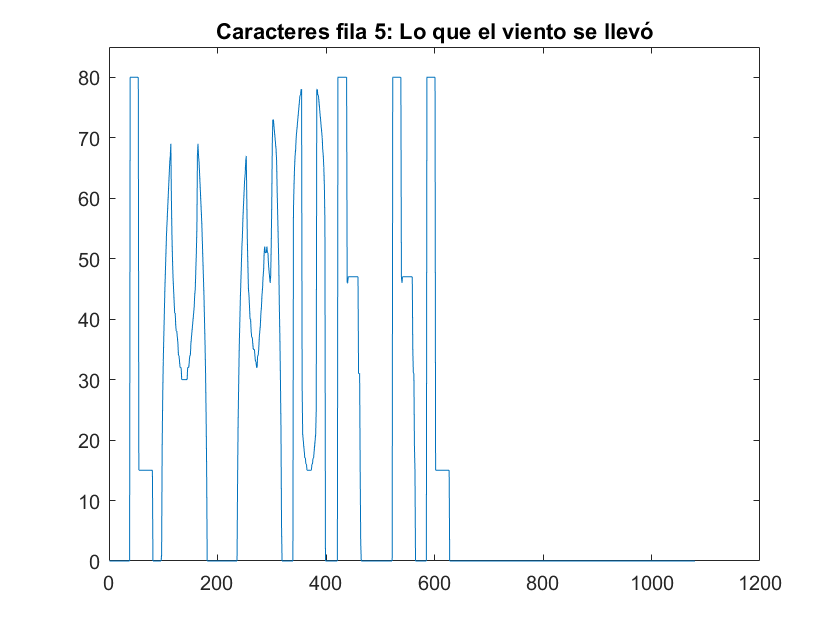

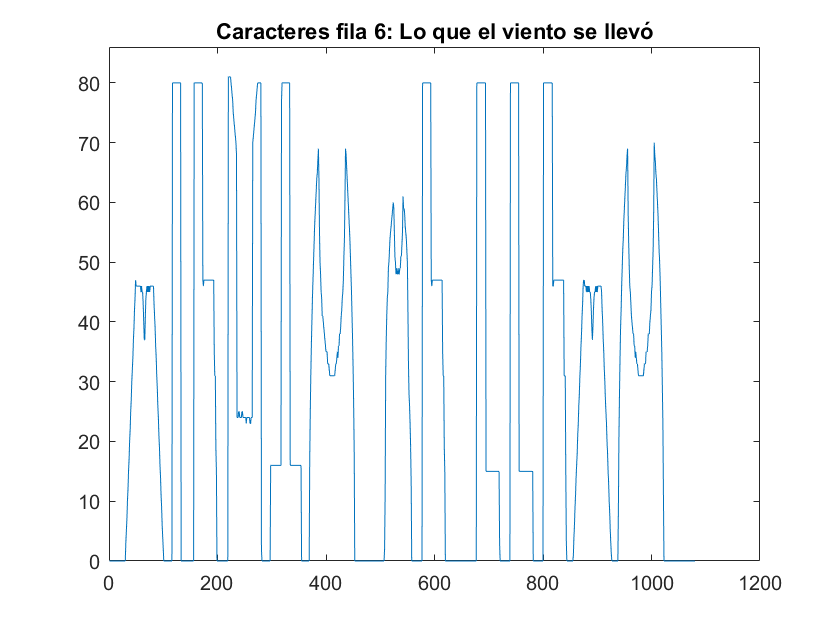

[caracteres1,indCar1]=numCaracteres(im1,filas1,indices1,'Lo que el viento se llevó');

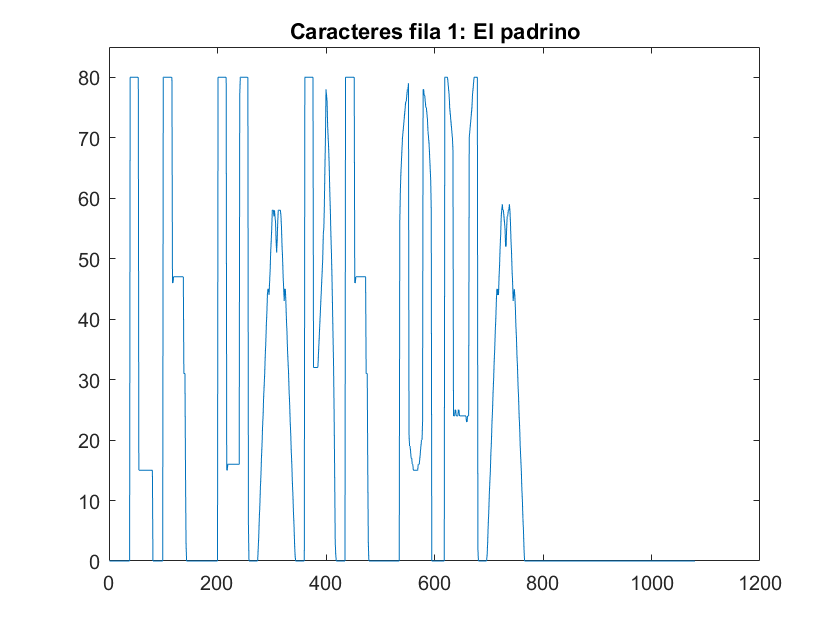

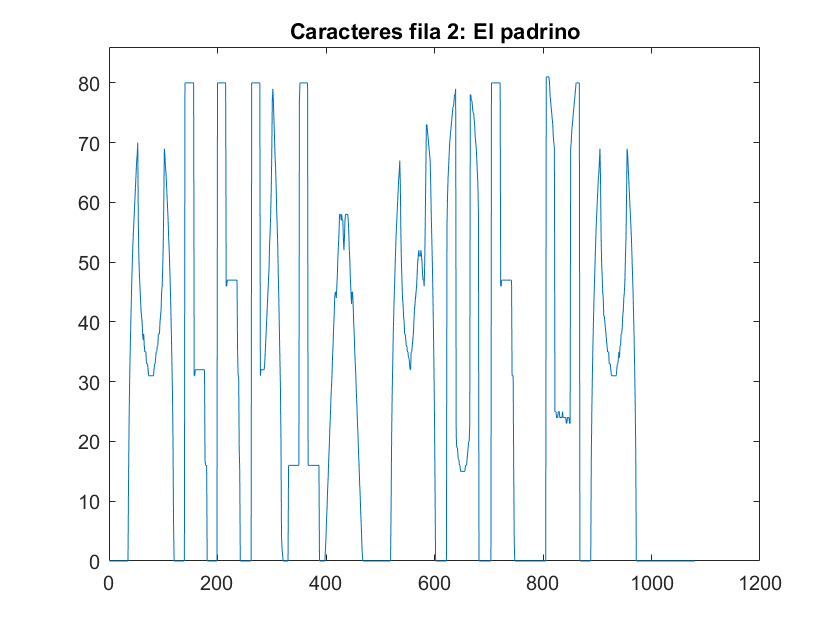

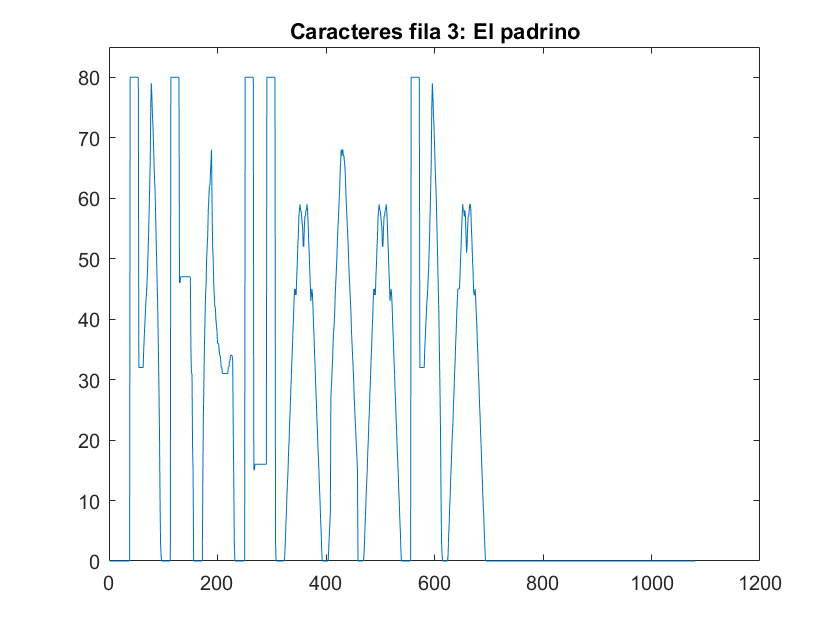

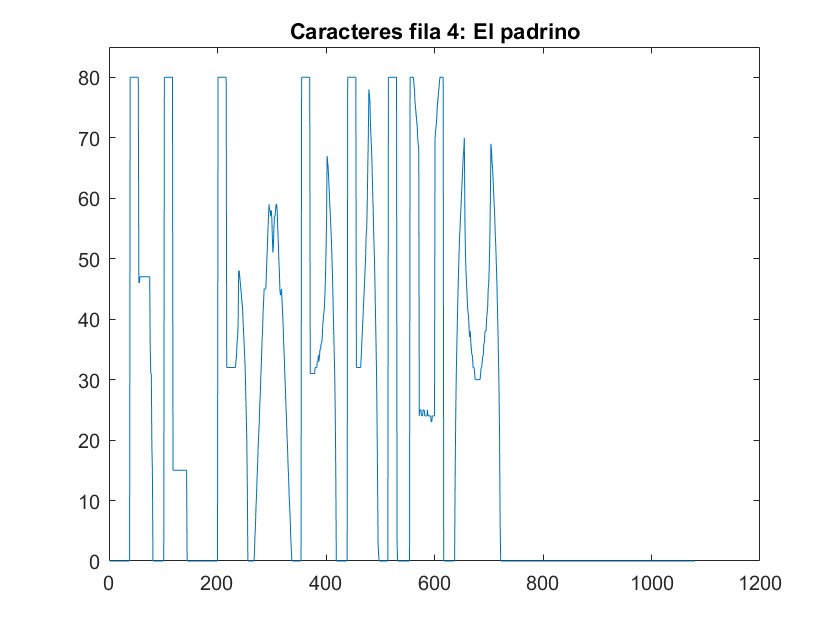


[caracteres2,indCar2]=numCaracteres(im2,filas2,indices2,'El padrino');

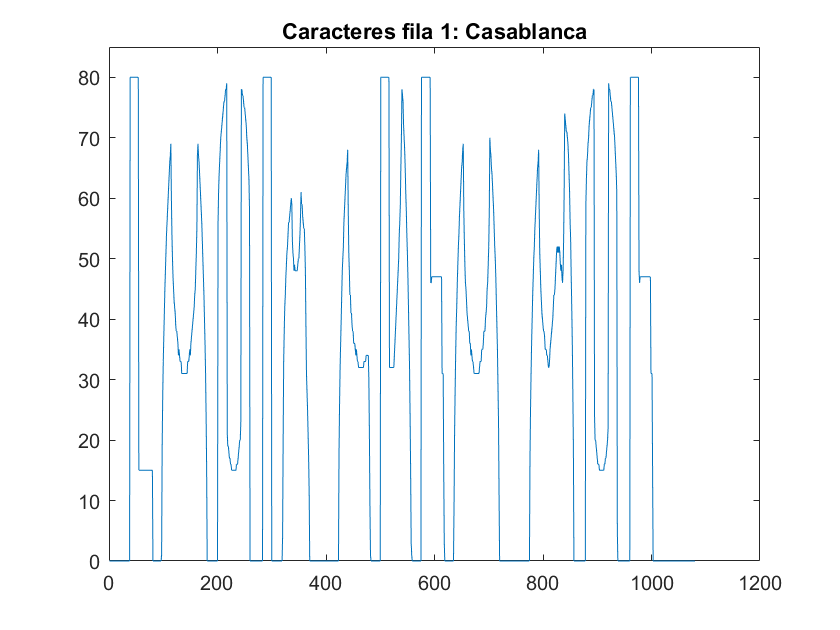

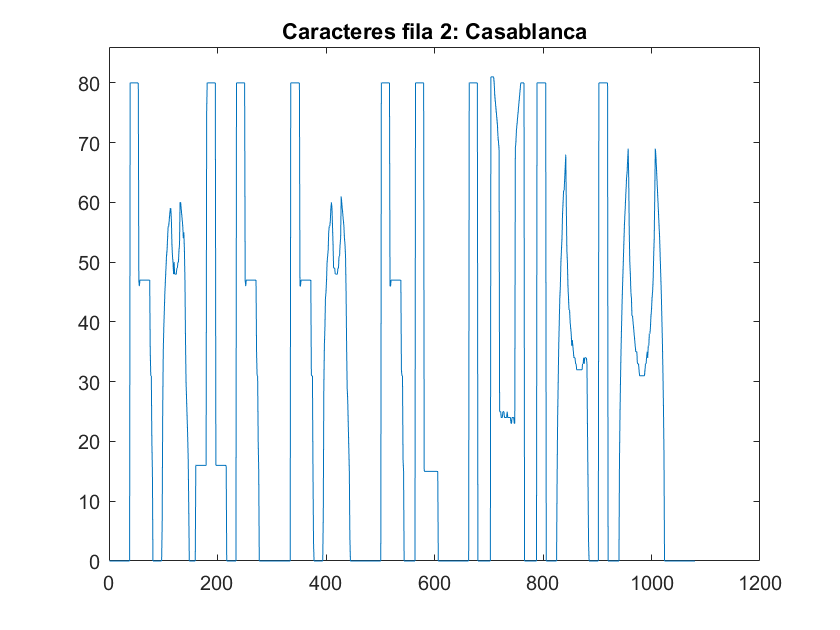

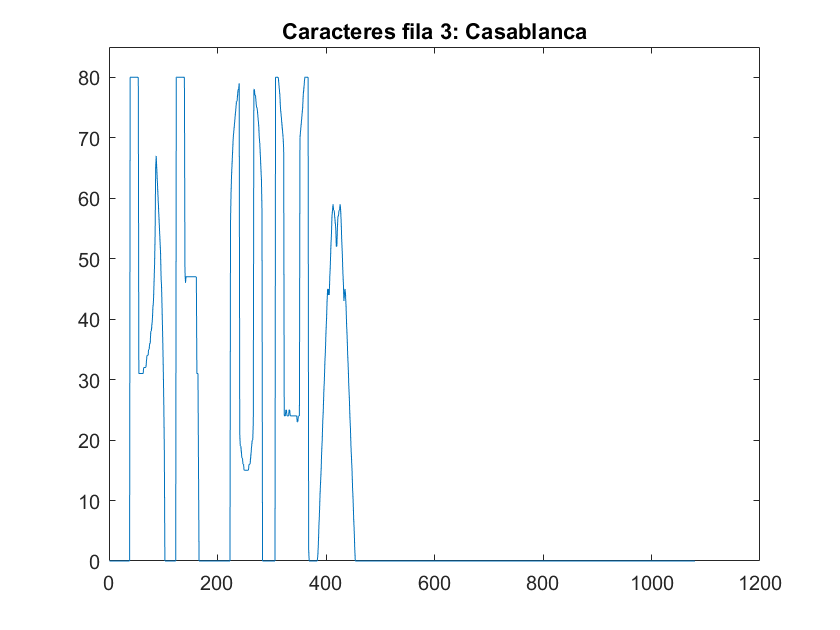

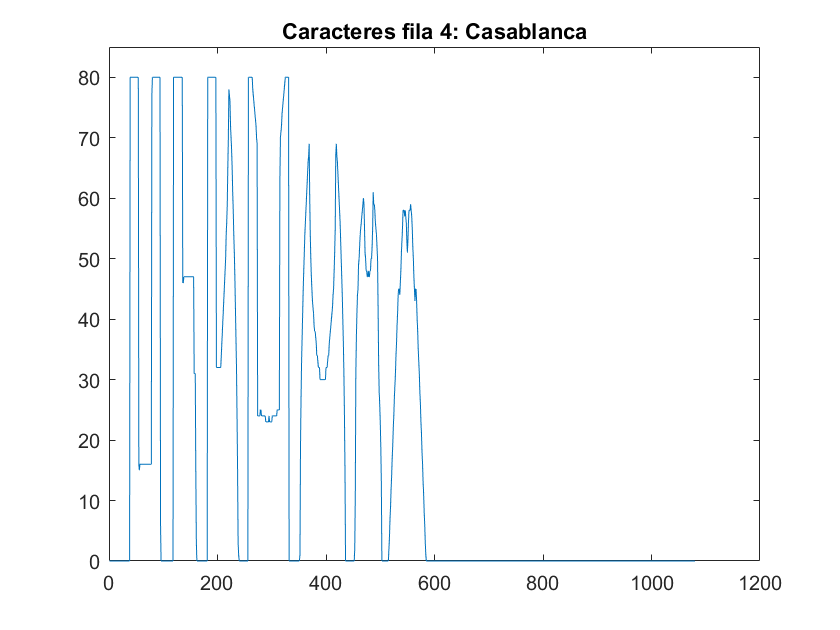

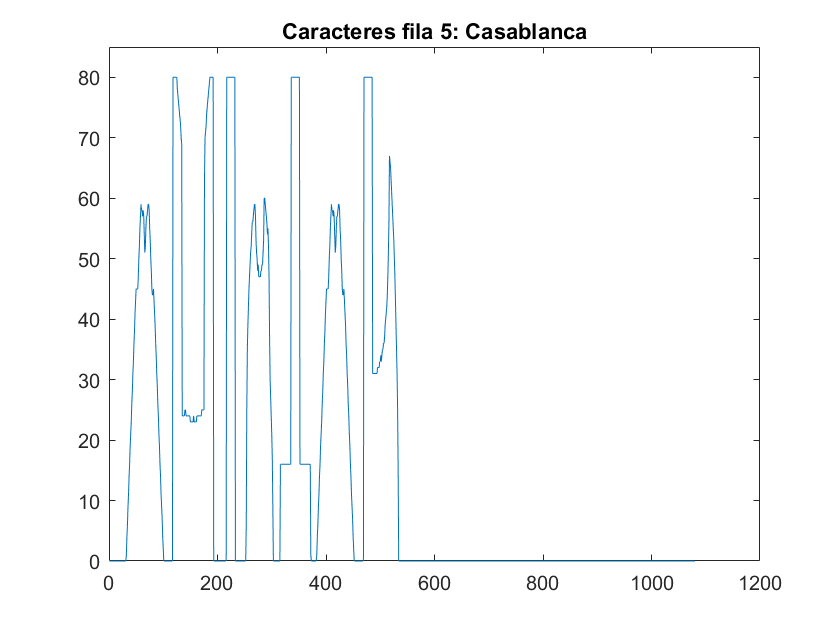

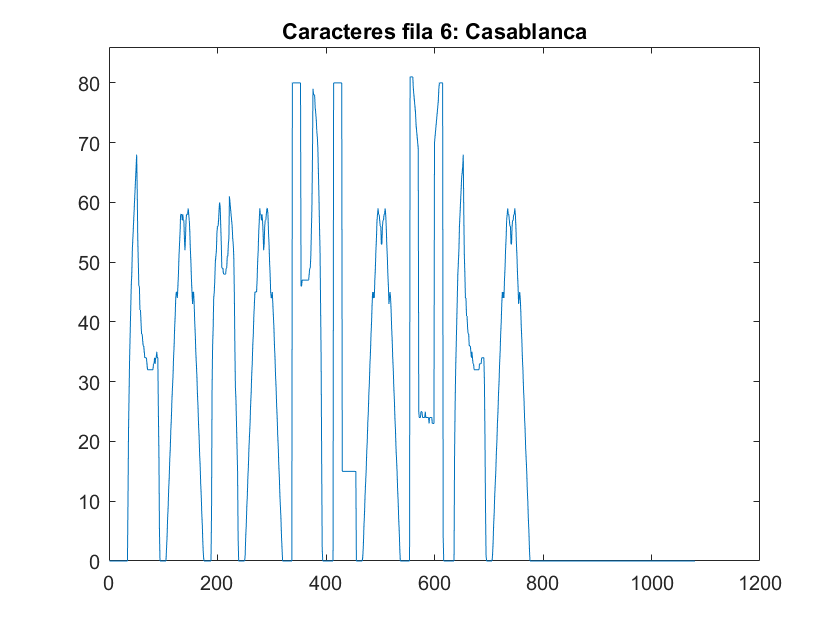


[caracteres3,indCar3]=numCaracteres(im3,filas3,indices3,'Casablanca');

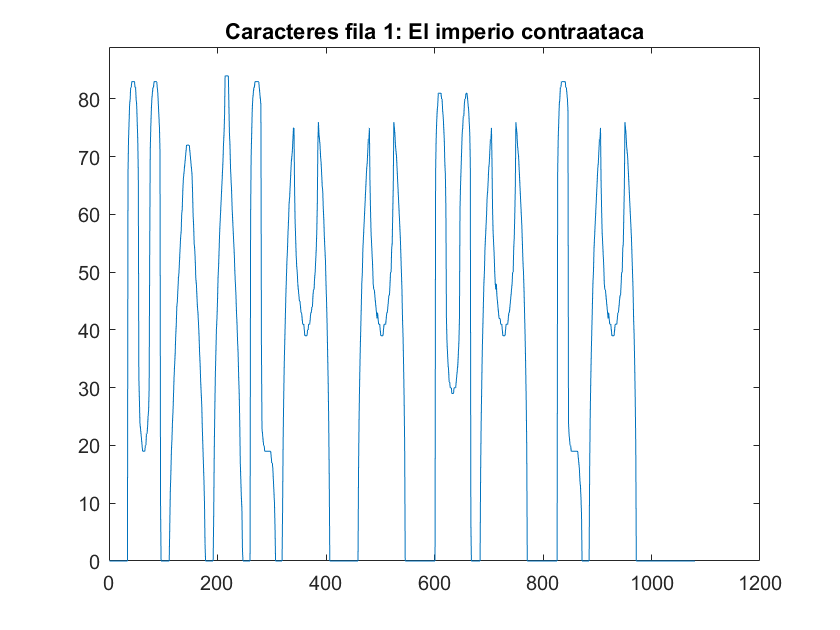

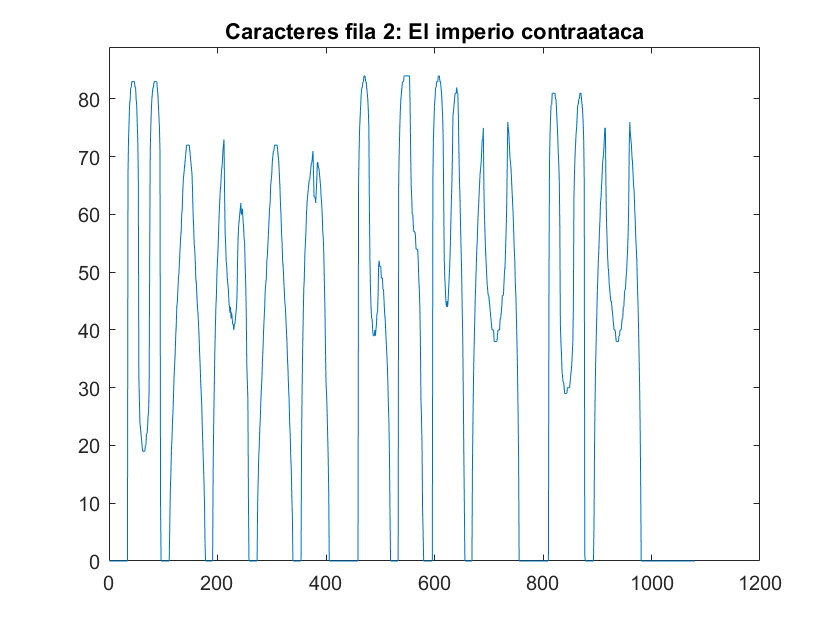

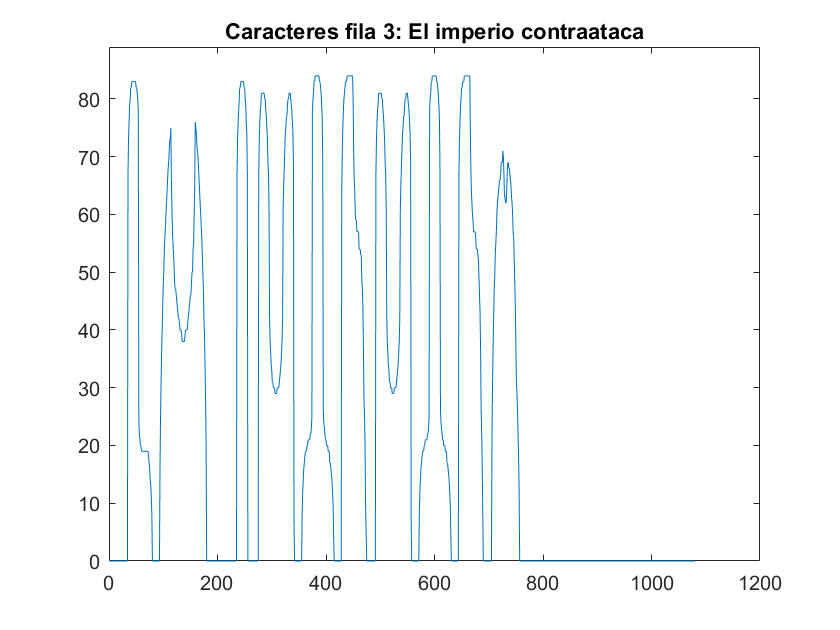

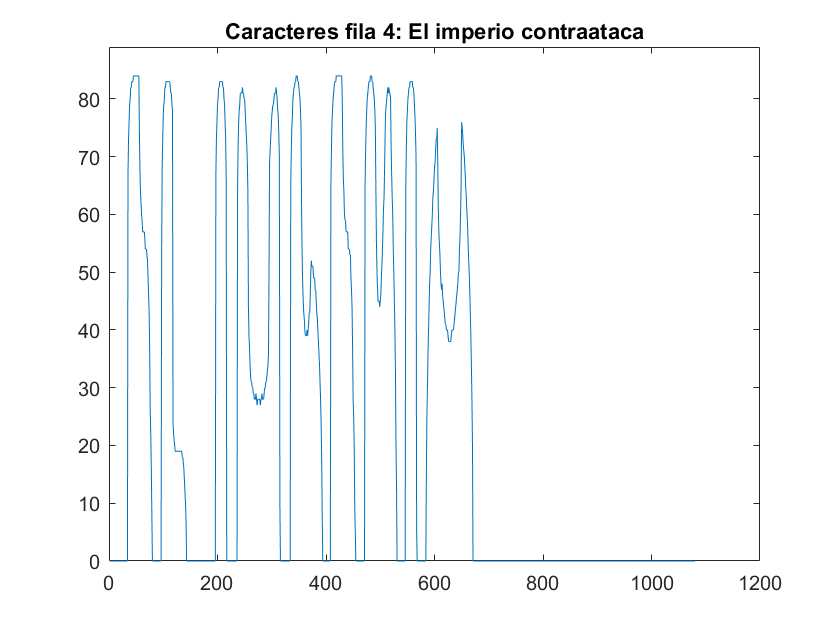

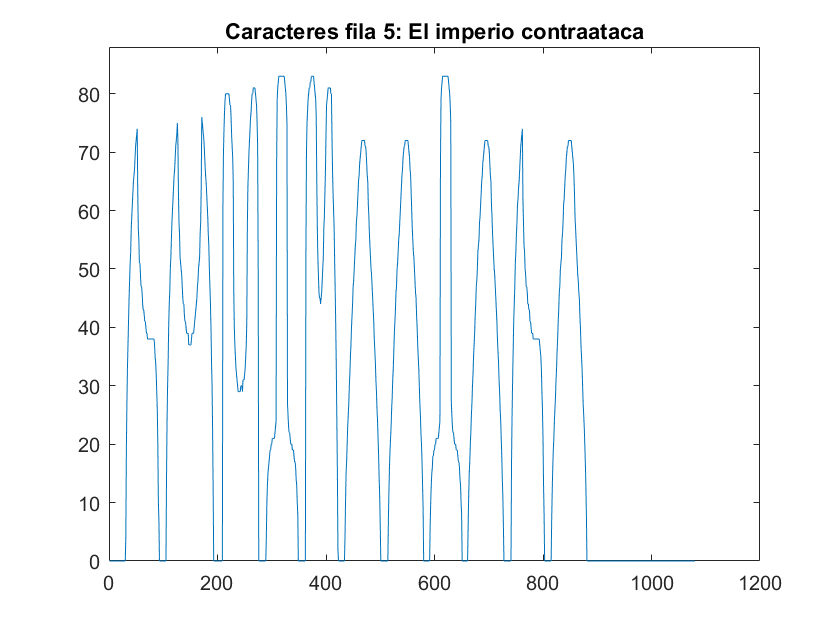


[caracteres4,indCar4]=numCaracteres(im4,filas4,indices4,'El imperio contraataca');

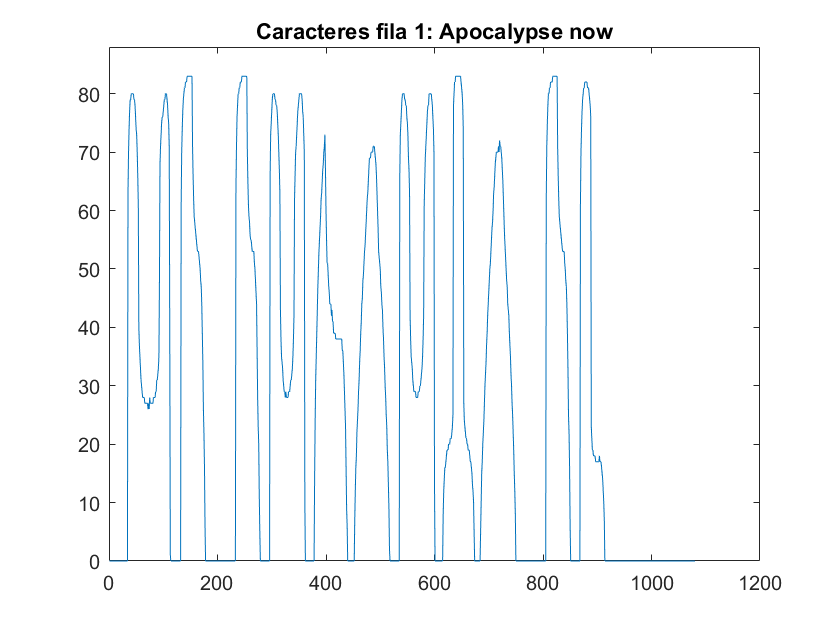

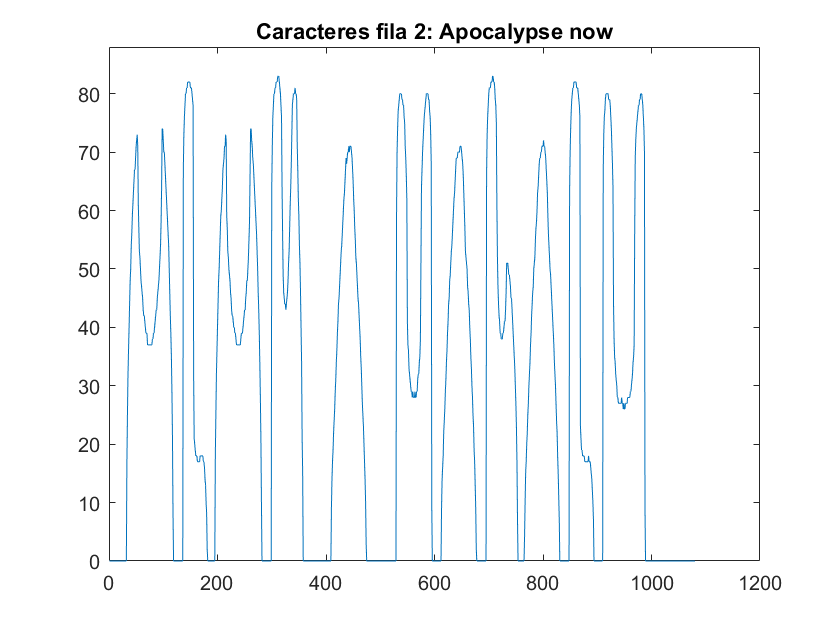

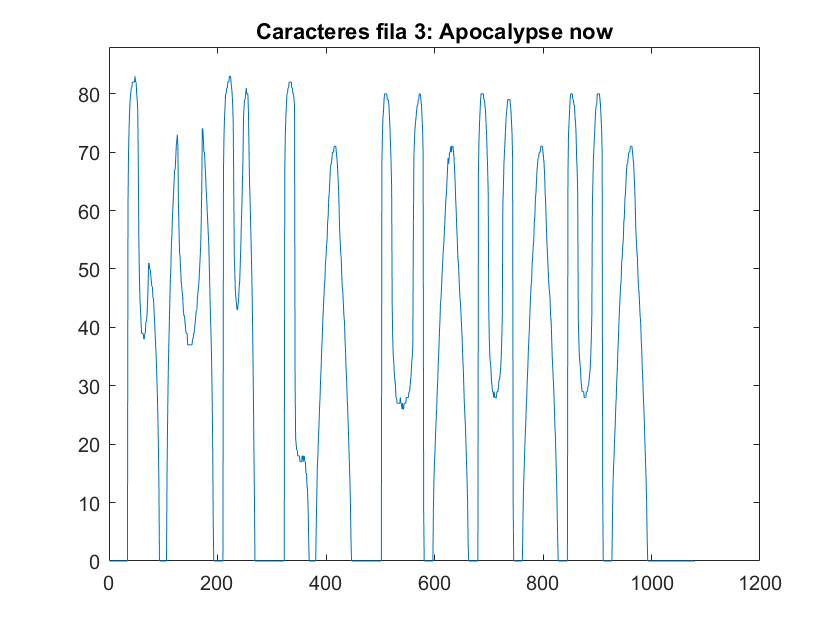

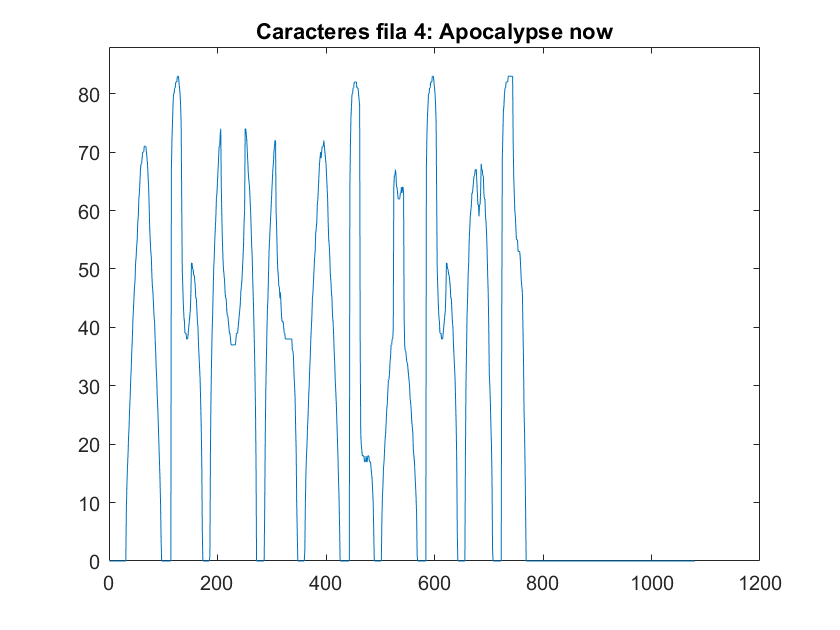

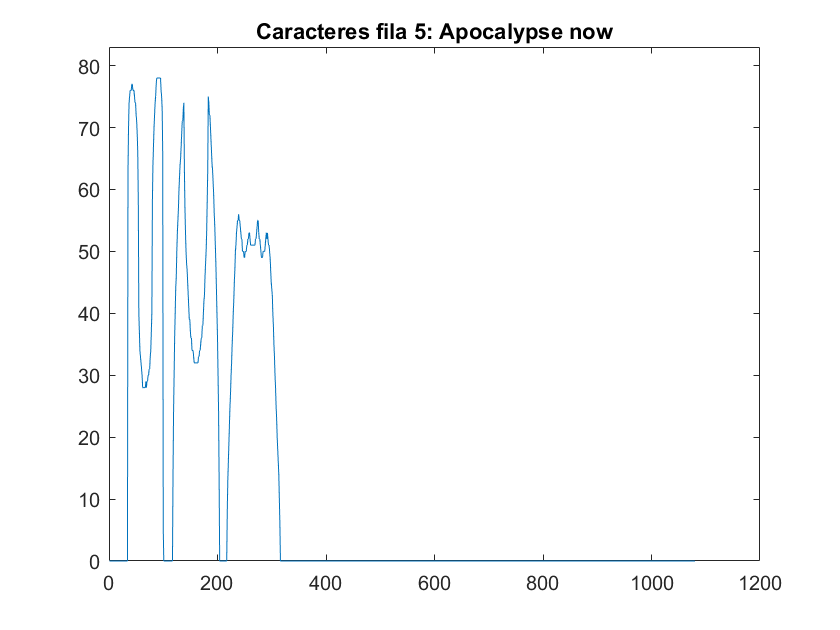


[caracteres5,indCar5]=numCaracteres(im5,filas5,indices5,'Apocalypse now');

### Tarea 4: Procesamiento de caracteres

Mediante el empleo de la función *procesCaract*, se obtienen las matrices que contienen los distintos caracteres presentes en las imagenes. En prinicipio, se corresponden con fragmentos de la matriz original. Sin embargo, en futuras tareas se requerirá que éstas sean cuadradas y, por este motivo, la función *procesCaract*, si se precisa, rellena con ceros (negro) las matrices que contienen los caracteres, logrando que el número de filas y el número de columnas se igualen.

carProces1=procesCaract(im1,filas1,indices1,caracteres1,indCar1);

carProces2=procesCaract(im2,filas2,indices2,caracteres2,indCar2);

carProces3=procesCaract(im3,filas3,indices3,caracteres3,indCar3);

carProces4=procesCaract(im4,filas4,indices4,caracteres4,indCar4);

carProces5=procesCaract(im5,filas5,indices5,caracteres5,indCar5);

### Tarea 5: Creación del alfabeto

En esta tarea, se obtienen las matrices (cuadradas) de los caracteres que se tomarán como referente en la tarea final del proyecto: *Reconocimiento de caracteres*. Se debe tener en cuenta que la imagen proporcionada para la obtención de estos caracteres de referencia deberá contener el alfabeto inglés, respetando tanto su contenido como su orden.

alf=alfabeto('alfabeto.png');

### Tarea 6: Reconociemiento de caracteres

El reconocimiento de caracteres constituye la última tarea de este proyecto. Para su desarrollo, se emplea la función *reconocimiento*, que identifica cada caracter y introduce espacios y saltos de línea entre ellos, según se precise. Esta función devuelve un *string* con el resultado y, mediante la función *fprintf,* escribimos dicho contenido en un archivo de texto del mismo nombre que el archivo de la imagen orginal.

f1=fopen("loqueelviento.txt",'wt');
fprintf(f1, reconocimiento(alf,carProces1,indCar1,caracteres1));
fclose(f1);

f2=fopen("elpadrino.txt",'wt');
fprintf(f2, reconocimiento(alf,carProces2,indCar2,caracteres2));
fclose(f2);

f3=fopen("casablanca.txt",'wt');
fprintf(f3, reconocimiento(alf,carProces3,indCar3,caracteres3));
fclose(f3);

f4=fopen("elimperiocontraataca.txt",'wt');
fprintf(f4, reconocimiento(alf,carProces4,indCar4,caracteres4));
fclose(f4);

f5=fopen("apocalypsenow.txt",'wt');
fprintf(f5, reconocimiento(alf,carProces5,indCar5,caracteres5));
fclose(f5);

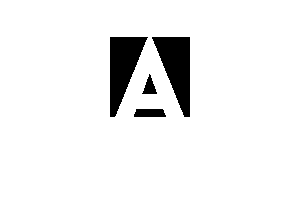

imshow(alf.A);

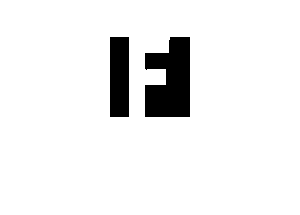

imshow(carProces1.f1c1)